#### **MATLAB simulation description**

A simplified attitude dynamics simulation of a CubeSat equipped with a single reaction wheel was implemented in MATLAB.

The satellite is modeled as a rigid body rotating around a single axis. The rotational dynamics are described using the following equations:$\[
\dot{\theta} = \omega
\]

\[
J\dot{\omega} = -\tau
\]

$

where θθ represents the spacecraft attitude angle, ωω is the angular velocity, JJ is the spacecraft moment of inertia, and ττ is the control torque generated by the reaction wheel.

The reaction wheel dynamics are modeled as: $\[
J_w \dot{\omega}_w = \tau
\]$

where JwJw� is the reaction wheel inertia and ωwωw� is the wheel angular velocity.

A simple feedback control law is implemented to stabilize the satellite and drive the attitude toward a desired reference angle. The simulation is performed using MATLAB's numerical solver `ode45`

clear; clc; close all;

#### Parameters

J  = 0.002;          % kg*m^2, CubeSat inertia around one axis
Jw = 1e-5;           % kg*m^2, reaction wheel inertia
Kp = 0.02;           % pointing proportional gain
Kd = 0.01;           % derivative gain
tau_max = 0.002;     % max wheel torque [N*m]

theta_ref = 0;       % desired pointing angle [rad]
omega_th  = 0.02;    % detumbling threshold [rad/s]

#### Initial conditions

theta0   = deg2rad(15);   % initial angle
omega0   = deg2rad(8);    % initial body rate
omega_w0 = 0;             % initial wheel speed

x0 = [theta0; omega0; omega_w0];

#### Simulation

tspan = [0 20];

[t,x] = ode45(@(t,x) dynamics_rw(t,x,J,Jw,Kp,Kd,tau_max,theta_ref,omega_th), tspan, x0);

theta   = x(:,1);
omega   = x(:,2);
omega_w = x(:,3);

#### Control history

tau = zeros(size(t));
for i = 1:length(t)
    tau(i) = control_rw(x(i,:).', Kp, Kd, tau_max, theta_ref, omega_th);
end

Turquoise color :)

color = [0 0.7 0.7];  

#### Plots

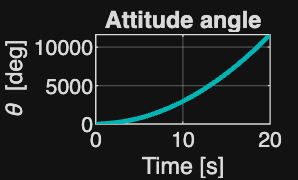

figure;
plot(t, rad2deg(theta), 'Color', color, 'LineWidth', 1.8);
grid on;
xlabel('Time [s]');
ylabel('\theta [deg]');
title('Attitude angle');

**Attitude angle** – shows how the satellite attitude evolves and converges toward the desired orientation.

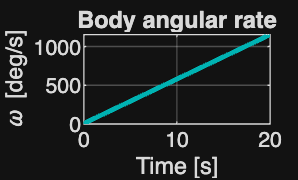

figure;
plot(t, rad2deg(omega), 'Color', color, 'LineWidth', 1.8);
grid on;
xlabel('Time [s]');
ylabel('\omega [deg/s]');
title('Body angular rate');

**Body angular rate** – shows the reduction of the spacecraft rotational velocity over time.

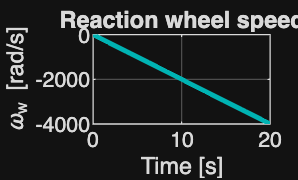

figure;
plot(t, omega_w, 'Color', color, 'LineWidth', 1.8);
grid on;
xlabel('Time [s]');
ylabel('\omega_w [rad/s]');
title('Reaction wheel speed');

**Reaction wheel speed** – represents the angular velocity of the reaction wheel used to generate the control torque.

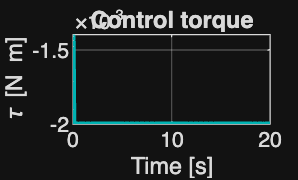

figure;
plot(t, tau, 'Color', color, 'LineWidth', 1.8);
grid on;
xlabel('Time [s]');
ylabel('\tau [N m]');
title('Control torque');

**Control torque** – represents the torque produced by the reaction wheel and applied to the spacecraft for attitude control